clc;clear;
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_total.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf80_total.mat")
% load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');

i = 3;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


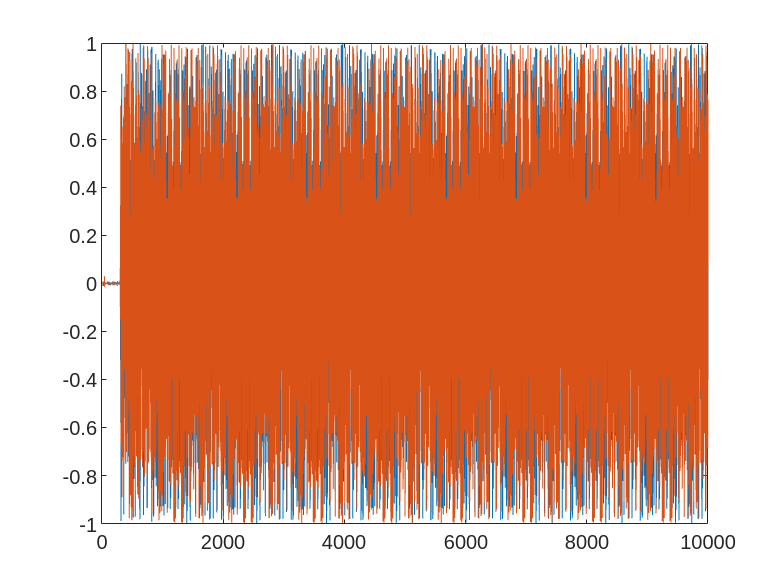

% time domain
N0 = 2514;
figure
plot(real(data))
hold on
plot(imag(data))
hold on

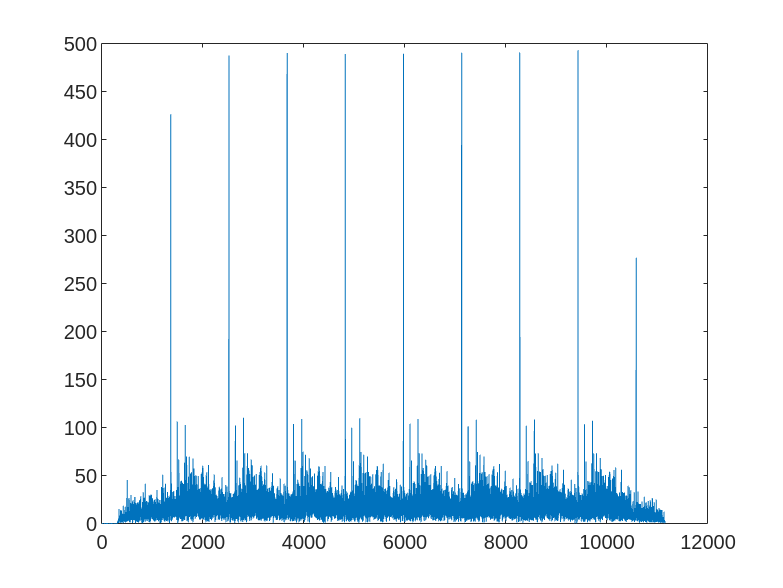

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result))
hold on


figure()
Fs = 200e6;
t = 0:1/Fs:0.000001-1/Fs % 1000 points

t = 1.0e-06 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


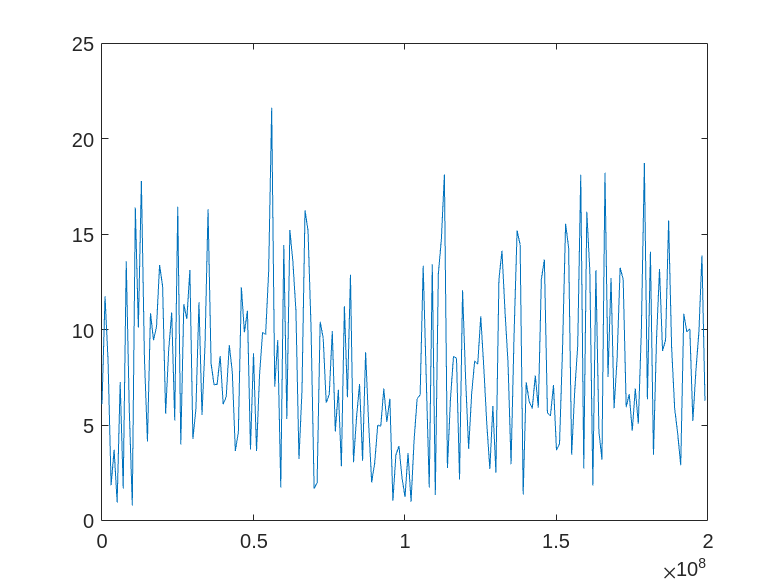

N = length(t);
y0 = abs(fft(data(N0+1:N0+N)));
f = (0:N-1)*Fs/N;
plot(f,y0);
% plot(abs(fftshift((fft(data(1:10000))))))
hold on 

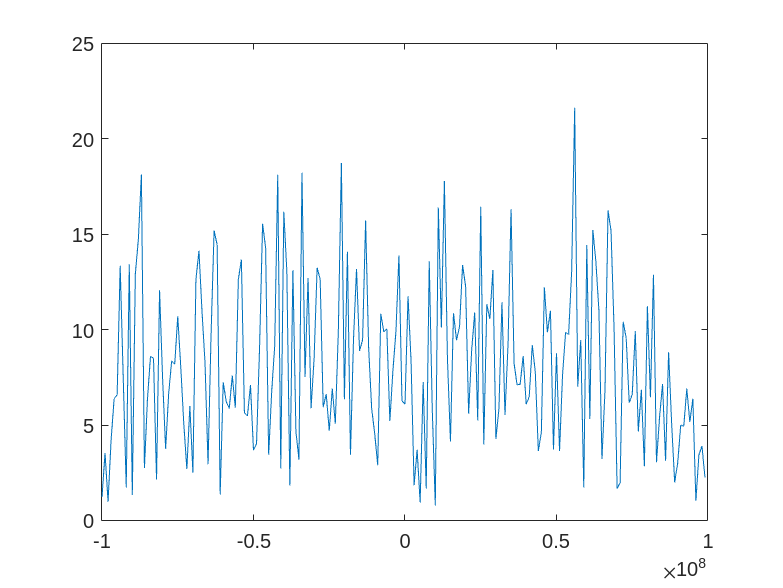


figure()
f1 = (0:N-1)*Fs/N-Fs/2;
y1 = abs(fftshift(fft(data(N0+1:N0+N))));
plot(f1,y1);
hold on

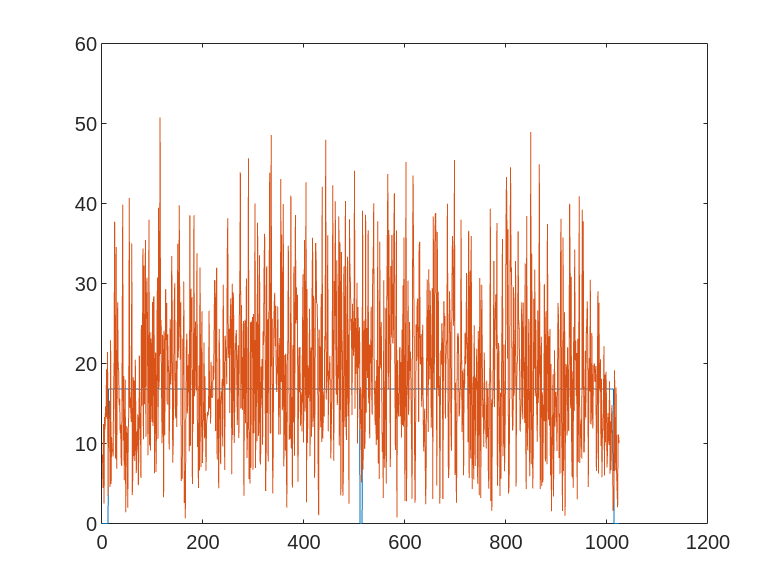


figure
cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
plot(abs(cfr_bb))
hold on

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;

pos = N0;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
plot(abs(cfr_recv))
hold on

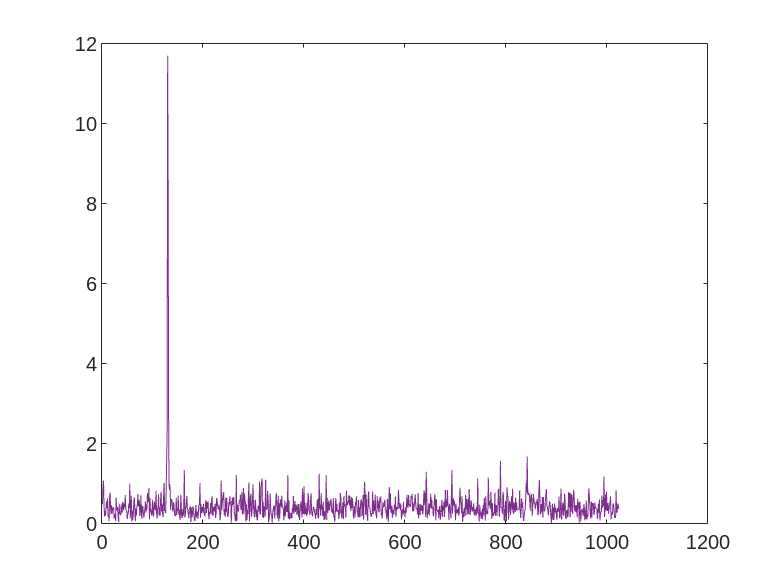

% plot(real(cfr_recv))
% hold on

cir1 = zeros(cfg.users, cfg.fftlen);

figure
for u=1:cfg.users
cir1(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(abs(cir1(1,:)))
hold on
end


% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_rx2.dat');
data = read_complex_binary('/mnt/tmp/usrp_heltf80_rx2.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf80.mat")
% load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');

i = 3;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


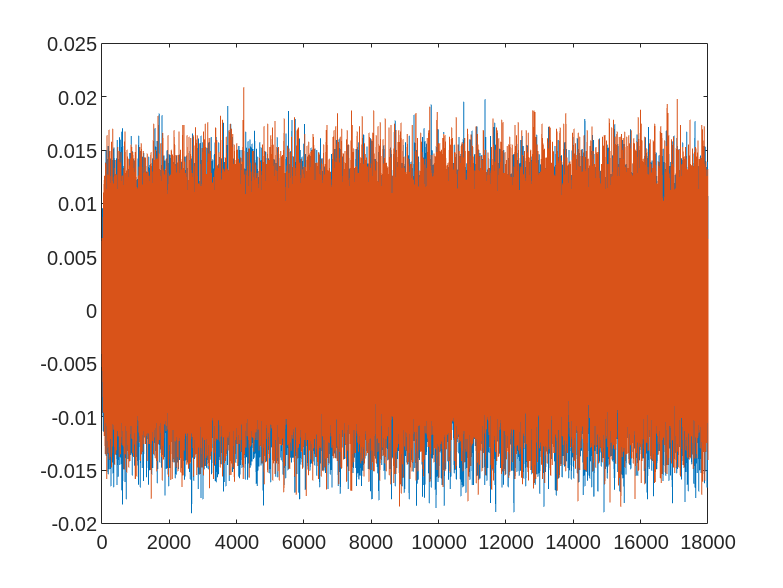

% time domain
N0 = 1621;
figure
plot(real(data(1:18000)))
hold on
plot(imag(data(1:18000)))

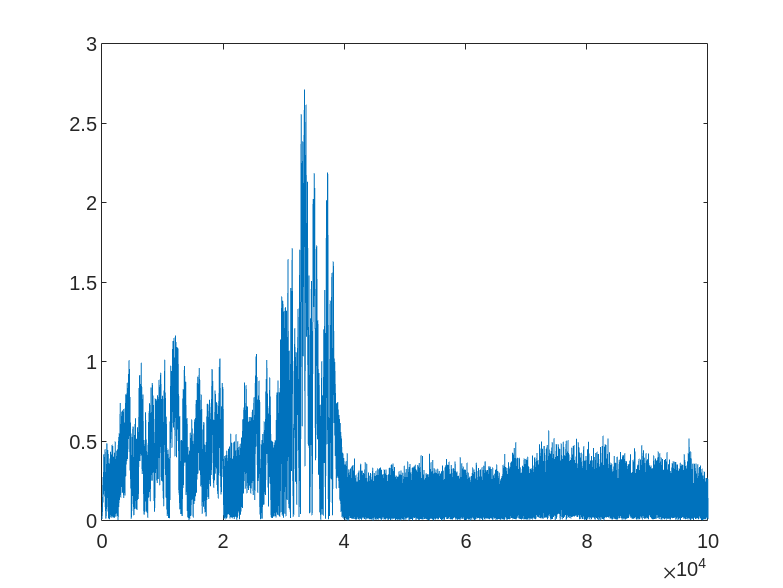

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result(1:100000)))
hold on

% decode part 

row = 0;
num = 80000

num = 80000

cir2 = zeros(num+1, cfg.fftlen);

% % cir2
% for N = N0:symbollen:N0+num*symbollen
% pos = N;
% row = row+1;
% cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
% 
% % plot(abs(cfr_recv))
% % hold on
% % plot(real(cfr_recv))
% % hold on
% 
% t3 = 1:12.5:12.5*1024;
% cir2(row,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% end

% % % rewrite cir2
data_length = num;
despread_data = [];
shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% find the index of the max values (relative position)
[~,max_index] = max(abs(shaped_corr),[],1)

max_index =          821        1020         690         990          15         713         927         216        1146         970         612         924           7        1083           8         877        1025         259         494         219         484        1127         161         706          33         860         733         299        1149           8         455        1052         367         159           2         158         201         803         883        1043         787         792         938         930         125         785        1038         429         878         398


%
col_index = 0:symbollen:(num-1)*symbollen

col_index =            0        1152        2304        3456        4608        5760        6912        8064        9216       10368       11520       12672       13824       14976       16128       17280       18432       19584       20736       21888       23040       24192       25344       26496       27648       28800       29952       31104       32256       33408       34560       35712       36864       38016       39168       40320       41472       42624       43776       44928       46080       47232       48384       49536       50688       51840       52992       54144       55296       56448


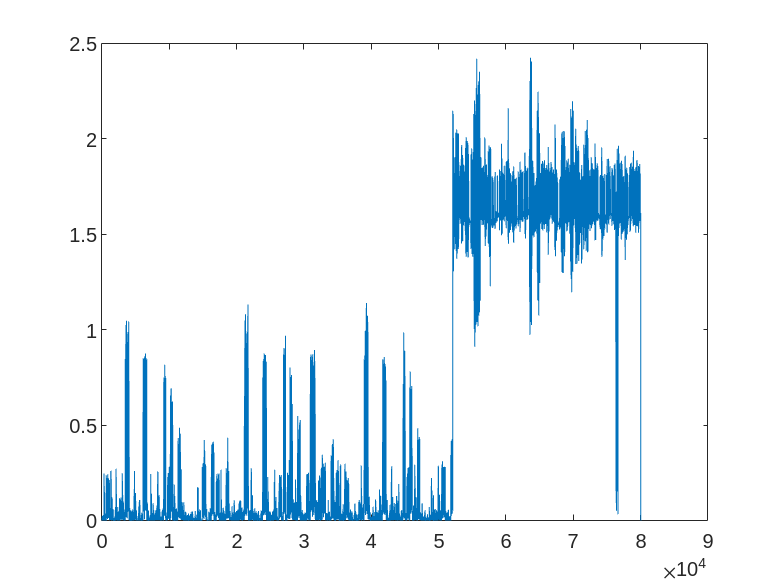

really_index = max_index+col_index;
despread_data = corr_result(max_index+col_index);
% for loop
% cfr_recv = zeros(num,1024);
start_index = really_index + ones(1,num) *(gilen+1);
end_index = really_index + ones(1,num) * symbollen;
for i = 1 : num
    cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
    cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
end

figure
plot(abs(cir2(:,128)))
hold on

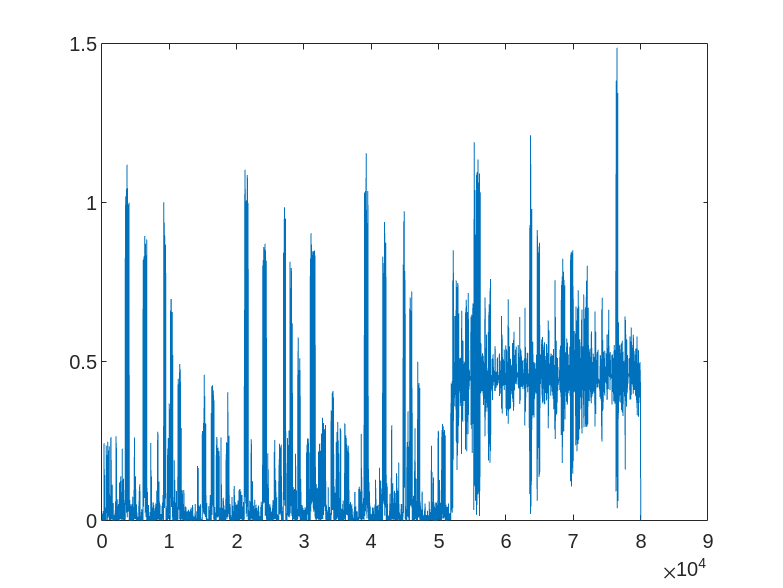


figure
plot(abs(cir2(:,129)))
hold on

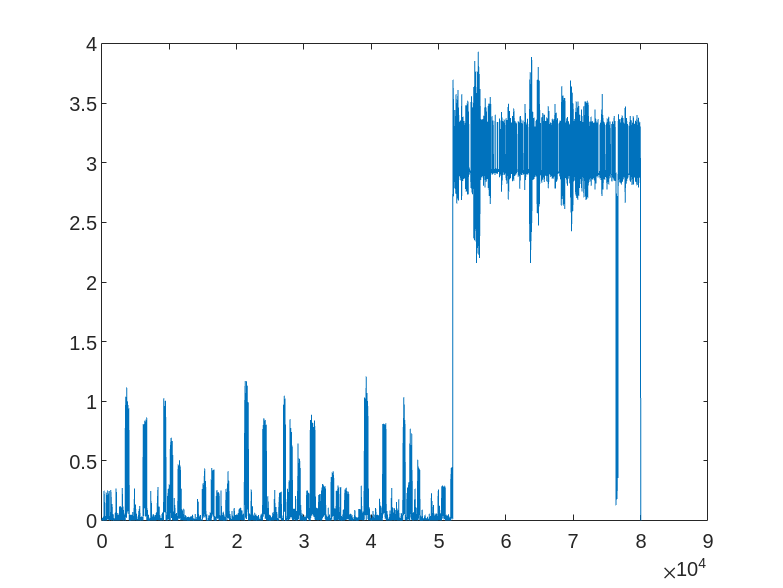


figure
plot(abs(cir2(:,130)))
hold on

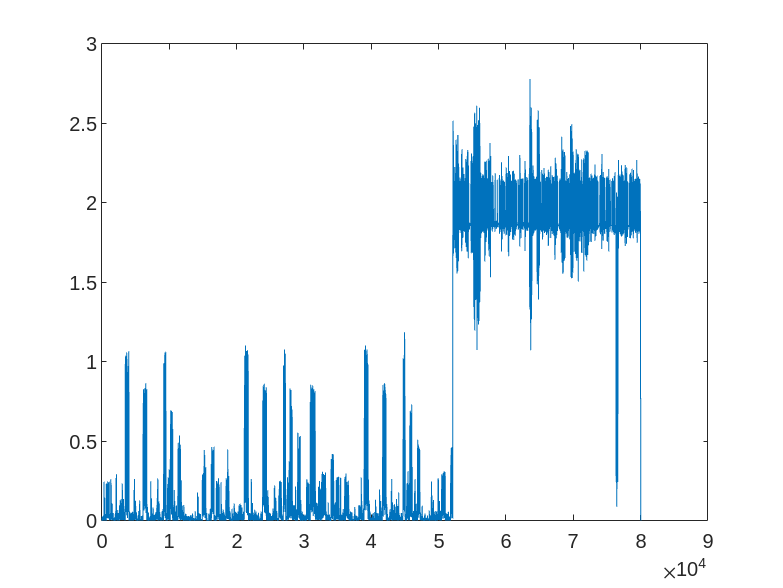


figure
plot(abs(cir2(:,131)))
hold on

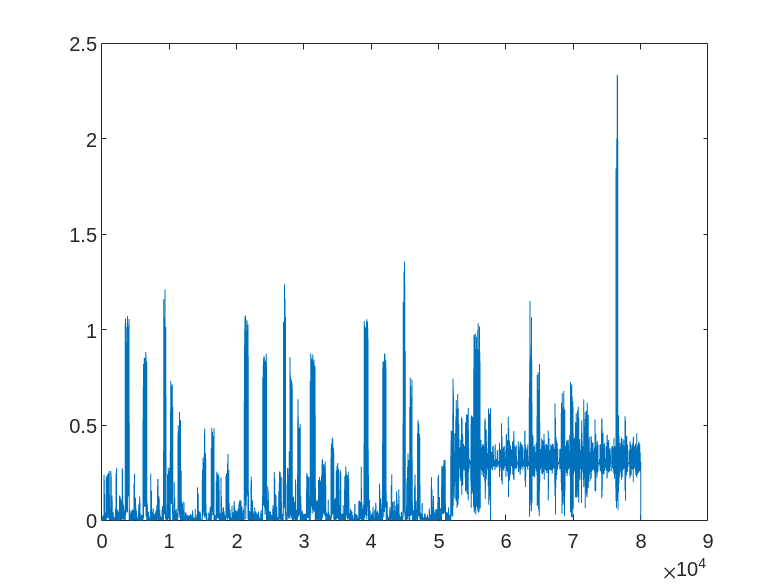


figure
plot(abs(cir2(:,132)))
hold on

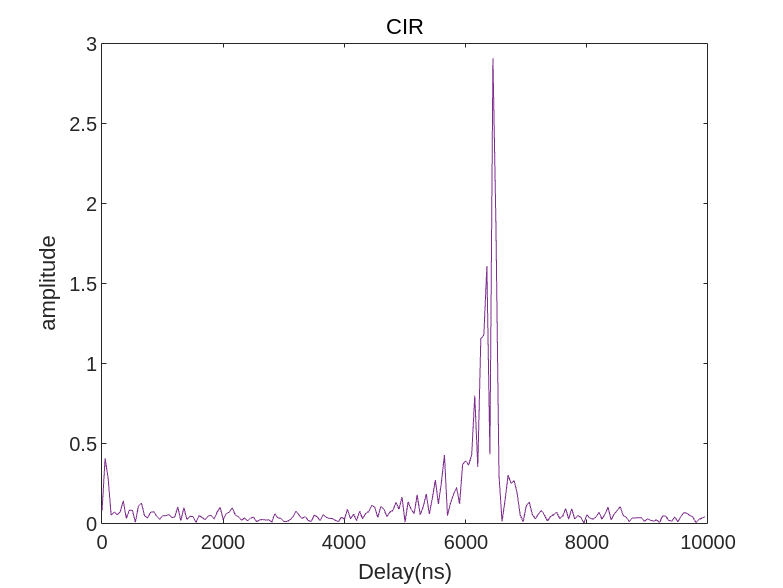


figure
for u=1:cfg.users
cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(1:50:50*200,abs(cir2(1,1:200)))
% plot(1:50:50*1024, abs(cir2(1,:)))
hold on

end
xlabel('Delay(ns)')
ylabel('amplitude')
title('CIR')